n = 10; % dimension of Matrix A
m = 7;
EPS = 0.0001;

[A, eigenvalues] = getRandomMatEigs(n, m)

A =     3.5729    0.4981   -1.1231   -0.1224    0.5028   -0.4428    0.3266   -1.2226   -0.6469   -0.4968
    0.4981    4.8466   -0.0426   -0.2463   -0.4271   -0.7206   -1.3023    0.1465   -0.9222   -0.1576
   -1.1231   -0.0426    5.0538    0.0860   -1.7562   -0.3806    0.6244   -0.3307   -0.1328   -0.6633
   -0.1224   -0.2463    0.0860    4.8217   -0.4294   -0.2655   -0.6341   -0.3372   -0.7359   -0.2889
    0.5028   -0.4271   -1.7562   -0.4294    3.3118    0.4042   -1.2250   -0.1853    0.7151   -0.8299
   -0.4428   -0.7206   -0.3806   -0.2655    0.4042    3.5519    0.1347   -1.0711   -0.6346   -0.2916
    0.3266   -1.3023    0.6244   -0.6341   -1.2250    0.1347    3.2671   -0.3302    0.3062   -0.3683
   -1.2226    0.1465   -0.3307   -0.3372   -0.1853   -1.0711   -0.3302    4.4755    0.6311    0.0072
   -0.6469   -0.9222   -0.1328   -0.7359    0.7151   -0.6346    0.3062    0.6311    2.8567   -1.1390
   -0.4968   -0.1576   -0.6633   -0.2889   -0.8299   -0.2916   -0.3683    0.0072   -1.1

eigenvalues =      1
     2
     3
     4
     5
     6
     7
     6
     7
     1


b = randi(10, n, 1)

b =      9
     9
     9
     2
     9
    10
     1
     7
     1
     2


X =     10    20
    10    20
    10    20
    10    20
    10    20
    10    20
    10    20
    10    20
    10    20
    10    20


Y =      1     1
     2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9
    10    10


err_analitical = 1.0e-08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0003    0.0016    0.0002    0.0384    0.0005    0.1610    0.0000    0.0924    0.0002    0.0000    0.0179    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

F1 = 1.0e-08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0003    0.0016    0.0002    0.0384    0.0005    0.1610    0.0000    0.0924    0.0002    0.0000    0.0179    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

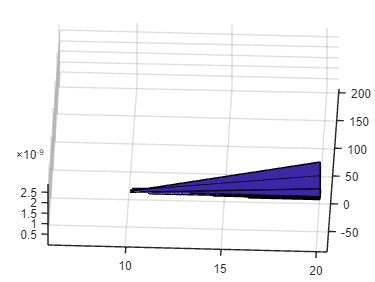


% compareAlgorithms(A, b, eigenvalues, EPS);

compareDFP_analiticalVsArmijo(EPS);

function [A, eigens] = getRandomMatEigs(n, m)
    uniqueEigs = (1:m)';
    eigens = [uniqueEigs; uniqueEigs(ceil(rand(n - m, 1) * m))];

    D = diag(eigens);
    V = orth(randi(n, n));
    % V = zeros(n, n);
    while rank(V) < n
        % disp("AAA");
        V = orth(randi(n, n));
    end
    A = V*D*V';
end

function alpha = min_quadratic_analitical(Fun, x, d, A)
    [~, grad, ~] = Fun(x);
    alpha = (-grad' * d) / (d' * (A' * A) * d);
end

% TODO: zabezpieczenia na zbyt mały krok
function alpha = armijo(Fun, x, d)
    rho = 0.2;
    K = 2.0;
    alpha = 1.0 * K;    % alpha_0 is divided by K with first iteration

    condition = true;
    while condition
        alpha = alpha / K;

        [F_0, grad_0, ~] = Fun(x);
        [F_a, ~, ~] = Fun(x + alpha*d);
        dF_0 = grad_0' * d;
        Fr_a = F_0 + rho*alpha*dF_0;

        condition = F_a > Fr_a;
    end
end

function compareAlgorithms(A, b, eigenvalues, EPS)
    n = length(b);

    % %%%%% SOLUTION EXACT %%%%%
    xE = A \ b
    
    
    x0 = zeros(n, 1);
    f = @(x)fun(x, A, b);
    % %%%%% SOLUTION FMINUNC %%%%%
    options = optimoptions("fminunc", Algorithm="quasi-newton", Display="iter", GradObj="on");
    [xFminunc, grad, hes] = fminunc(f, x0, options);
    errFminunc = norm(xE - xFminunc)
    
    % %%%%% SOLUTION DFP %%%%%
    alpha_analitical = @(x, d)min_quadratic_analitical(f, x, d, A);
    alpha_armijo = @(x, d)armijo(f, x, d);
    [xDFP, fval, it, err_h_inv] = DFP(f, x0, EPS, alpha_analitical);
    % [xDFP, fval, it, err_h_inv] = DFP(f, x0, EPS, alpha_armijo);
    % err_h_inv
    errDFP = norm(xE - xDFP)
    
    % %%%%% SOLUTION NS %%%%%
    % lambda = eig(A);    % TODO: A*A'??
    [xNS, fval, it] = NS_eigs(f, x0, EPS, eigenvalues.^2);
    errNS = norm(xE - xNS)
end

function compareDFP_analiticalVsArmijo(EPS)
    err_analitical = [];
    err_armijo = [];
    N = 10:10:20;
    for n=N
        err_analiticalN = [];
        err_armijoN = [];
        for m = 1:n
            [A, eigenvalues] = getRandomMatEigs(n, m);
            b = randi(10, n, 1);
            
            xE = A \ b;
        
            x0 = zeros(n, 1);
            f = @(x)fun(x, A, b);
        
            alpha_analitical = @(x, d)min_quadratic_analitical(f, x, d, A);
            [xDFP1, fval1, it1, err_h_inv1] = DFP(f, x0, EPS, alpha_analitical);
        
            alpha_armijo = @(x, d)armijo(f, x, d);
            [xDFP2, fval2, it2, err_h_inv2] = DFP(f, x0, EPS, alpha_armijo);

            err_analiticalN = [err_analiticalN, norm(xE - xDFP1)];
            err_armijoN = [err_armijoN, norm(xE - xDFP2)];
            % it1
            % it2
        end
        err_analiticalN = [err_analiticalN, zeros(1, 200-n)];
        err_armijoN = [err_armijoN, zeros(1, 200-n)];

        err_analitical = [err_analitical; err_analiticalN];
        err_armijo = [err_armijo; err_armijoN];
    end
    
    x = N;
    y = 1:200;
    % z = 1:10;
    [X, Y] = meshgrid(x, y)
    err_analitical
    F1 = err_analitical(x./10, y)
    surf(X, Y, F1');
end